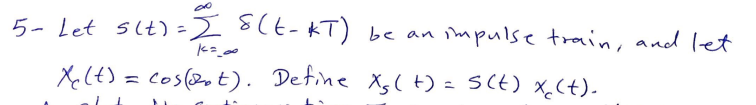

w = 1;
T = 2*pi/(3*w)

T = 2.0944

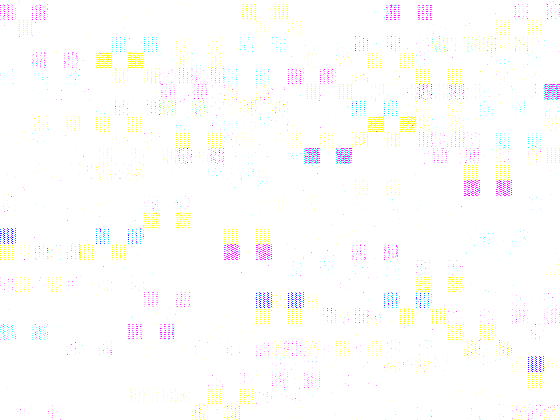


n = -10:T:10;
x_c = cos(w*n);

dtft = fft(x_c);
plot(abs(fftshift(dtft)))

w = 1;
T = 4*pi/(3*w)

T = 4.1888

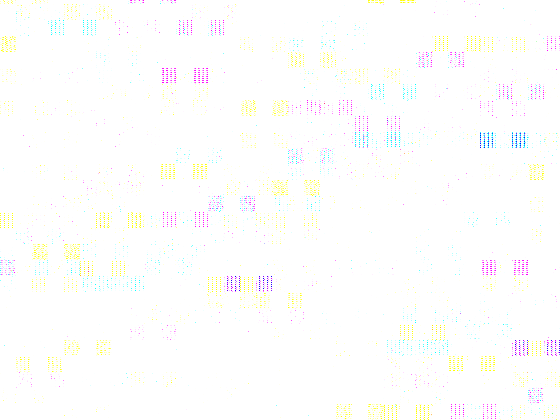


n = -10:T:10;
x_c = cos(w*n);

dtft = fft(x_c);
plot(abs(fftshift(dtft)))

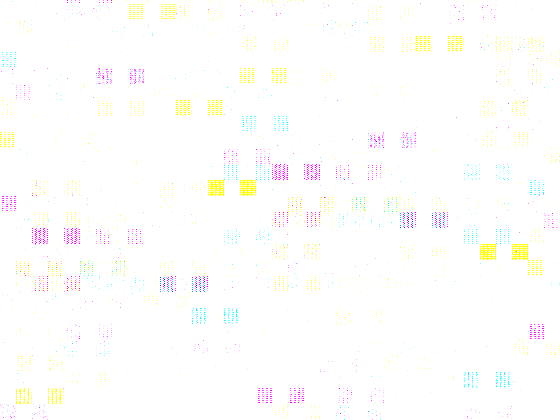

T = 0.0001;
M = 3;
L = 2;
n = -1:T:10;
x = (0.5.^n).*heaviside(n);
x_ed = ((M/L)*((0.5).^(M*n/L)).*heaviside(M*n/L)).*(1+exp(-1i*L*pi/M)+exp(-1i*2*L*pi/M));

figure(1)
subplot(2,1,1)
plot(n, x)
title("Original x(n)")

subplot(2,1,2)
plot(n, abs(x_ed))
title("Downsampled then upsampled x(n)")

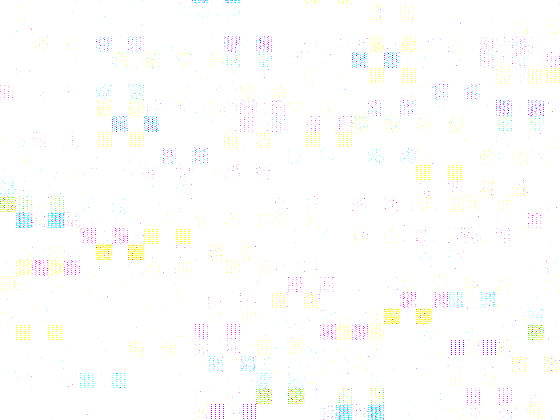


figure(2)
subplot(2,1,1)
plot(n, abs(fftshift(fft(x))))
title("Original X(W)")
xlim([4.48,4.52])

subplot(2,1,2)
plot(n, abs(fftshift(fft(x_ed))))
title("Downsampled then upsampled X(W)")
xlim([4.48,4.52])

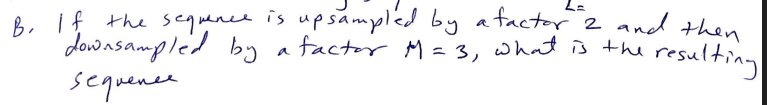

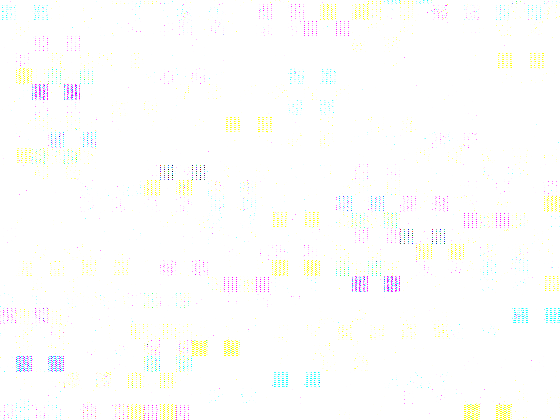

T = 0.0001;
M = 2;
L = 3;
n = -1:T:10;
x = (0.5.^n).*heaviside(n);
x_ed = ((M/L)*((0.5).^(M*n/L)).*heaviside(M*n/L)).*(1+exp(-1i*L*pi/M)+exp(-1i*2*L*pi/M));

figure(1)
subplot(2,1,1)
plot(n, x)
title("Original x(n)")

subplot(2,1,2)
plot(n, abs(x_ed))
title("Downsampled then upsampled x(n)")

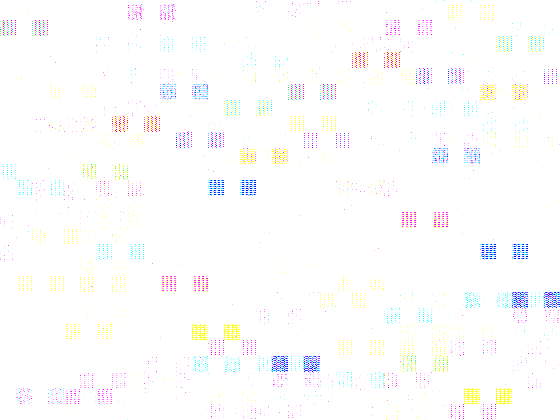


figure(2).
subplot(2,1,1)
plot(n, abs(fftshift(fft(x))))
title("Original X(W)")
xlim([4.48,4.52])

subplot(2,1,2)
plot(n, abs(fftshift(fft(x_ed))))
title("Downsampled then upsampled X(W)")
xlim([4.48,4.52])